# This is the live script for ESE 6190 HW7 Explicit, Robust, & Hybrid MPC Exercise 3.3

clear all
clc

## 3.3.iii: Case study with different settings

% system parameters for Ts = 0.02
Ac = [0.9786 -0.021; 1.8892 0.8841];
E = [0.0221; 0.0214];
Ad = [1 0; 0 0.9048];
Vdc = 20;
A1 = Ac;
B1 = E*Vdc;
A2 = Ac;
B2 = E*Vdc;
A3 = Ad;
B3 = E*Vdc;
Ts = 0.02;
Q = eye(2);

% overall constriants
xmin = [-1;-10];
xmax = [1;10];

% sub-system domian
xmin1 = xmin;
xmax1 = xmax;
umin1 = 1;
umax1 = 1;

xmin2 = [0;-10];
xmax2 = xmax;
umin2 = 0;
umax2 = 0;

xmin3 = xmin;
xmax3 = [0;10];
umin3 = 0;
umax3 = 0;


% PWA system definition, also set the domain of the state and input for the
% each piece of the system to work
sys1 = LTISystem('A', A1, 'B', B1,'Ts', Ts);
R1 = Polyhedron('lb', [xmin1; umin1], 'ub',[xmax1; umax1]);
sys1.setDomain('xu', R1);

sys2 = LTISystem('A', A2, 'B', B2,'Ts', Ts);
R2 = Polyhedron('lb', [xmin2; umin2], 'ub',[xmax2; umax2]);
sys2.setDomain('xu', R2);

sys3 = LTISystem('A', A3, 'B', B3,'Ts', Ts);
R3 = Polyhedron('lb', [xmin3; umin3], 'ub',[xmax3; umax3]);
sys3.setDomain('xu', R3);

% assemble each piece to generate PWA system
model = PWASystem([sys1, sys2, sys3]);

State/input/output constraints not imported, set them manually afterwards.


model.x.min = [-1,-10]; 
model.x.max = [1,10];
model.u.min = 0; 
model.u.max = 1;

## case B: different initial condition, reference is 1V constant signal, horizon is 4, system is with Ts=0.02, 2-norm objective

% MPC controller design
model.x.with('reference');
model.x.reference = 'free';
model.x.penalty = QuadFunction(Q);
ctrl = MPCController(model, 4);
ehmpc = ctrl.toExplicit();

mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
Binary node 20/81
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
Binary node 40/81
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
Binary node 60/81
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
mpt_plcp: 1 regions
Binary

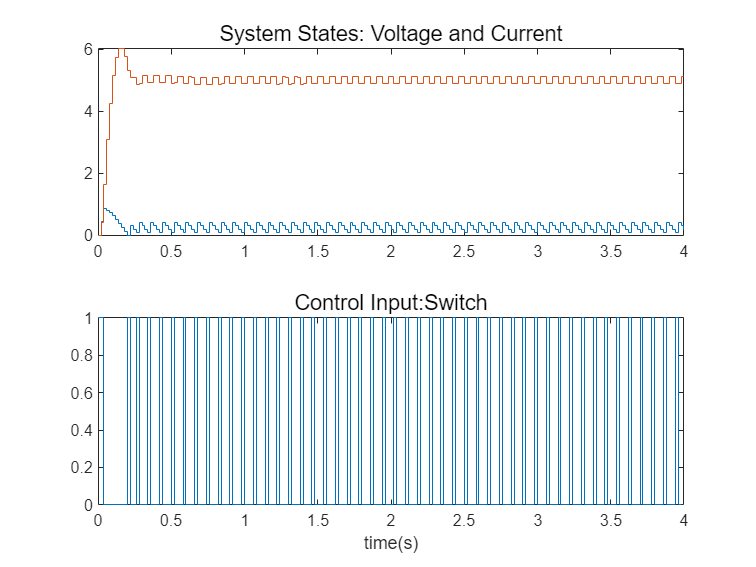


% simulation
plant = model;
loop = ClosedLoop(ehmpc, plant);
x0 = [0; 0];
Nsim = 200;
T = 0:Ts:Nsim*Ts;

% change the reference signal
xref = [0;5];
data = loop.simulate(x0, Nsim, 'x.reference', xref);
figure(); 
subplot(2,1,1); 
stairs(T,data.X');
xlim([0,Nsim*Ts]);
title('System States: Voltage and Current',FontSize=12)
subplot(2,1,2); 
stairs(T(1:end-1),data.U');
title('Control Input:Switch',FontSize=12)
xlabel('time(s)')

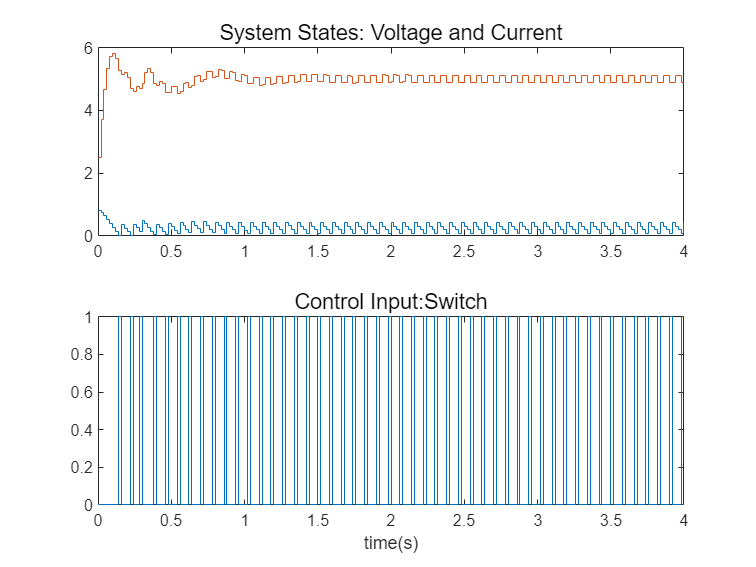

x0 = [0.8; 2.5];
% change the reference signal
xref = [0;5];
data = loop.simulate(x0, Nsim, 'x.reference', xref);
figure(); 
subplot(2,1,1); 
stairs(T,data.X');
xlim([0,Nsim*Ts]);
title('System States: Voltage and Current',FontSize=12)
subplot(2,1,2); 
stairs(T(1:end-1),data.U');
title('Control Input:Switch',FontSize=12)
xlabel('time(s)')